# RVC2: Chapter 7: Only trajectories


close all
clear
clc

## 7.1.2.3 6-axis industrial robot

mdl_puma560

p560

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, fastRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 



TE = p560.fkine(qz)

 

TE = 
         1         0         0    0.4521
         0         1         0     -0.15
         0         0         1    0.4318
         0         0         0         1



p560.tool = SE3(0, 0, 0.2);

p560.fkine(qz)

 

ans = 
         1         0         0    0.4521
         0         1         0     -0.15
         0         0         1    0.6318
         0         0         0         1



p560.base = SE3(0, 0, 30*0.0254);
p560.fkine(qz)

 

ans = 
         1         0         0    0.4521
         0         1         0     -0.15
         0         0         1     1.394
         0         0         0         1



p560.base = SE3(0,0,3) * SE3.Rx(pi);
p560.fkine(qz)

 

ans = 
         1         0         0    0.4521
         0        -1         0      0.15
         0         0        -1     2.368
         0         0         0         1


## 7.2  Inverse kinematics

## 7.2.2.1  Closed-form solution

mdl_puma560
qn

qn =          0    0.7854    3.1416         0    0.7854         0


T = p560.fkine(qn)

 

T = 
         0         0         1    0.5963
         0         1         0   -0.1501
        -1         0         0  -0.01435
         0         0         0         1


qi = p560.ikine6s(T)

qi =     2.6486   -3.9270    0.0940    2.5326    0.9743    0.3734


p560.fkine(qi)

 

ans = 
         0         0         1    0.5963
         0         1         0     -0.15
        -1         0         0  -0.01435
         0         0         0         1




qru = p560.ikine6s(T, 'ru')

qru =    -0.0000    0.7854    3.1416   -0.0000    0.7854    0.0000


qrd = p560.ikine6s(T, 'rd')

qrd =    -0.0000   -0.8335    0.0940   -3.1416    0.8312    3.1416


figure
p560.plot(qru)
title ('right handed elbown up')
figure
p560.plot(qrd);
title ('right handed elbown down')

p560.ikine6s( SE3(3, 0, 0) )

ans =    NaN   NaN   NaN   NaN   NaN   NaN



% 
    q = [0 pi/4 pi 0.1 0 0.2];
    p560.plot(q);

q1=p560.ikine6s(p560.fkine(q), 'ru')

q1 =    -0.0000    0.7854    3.1416   -3.0409    0.0000   -2.9423


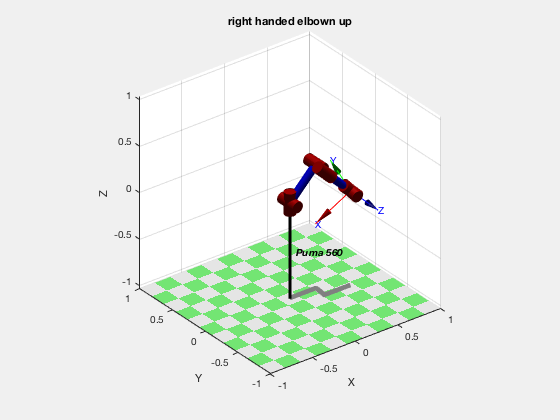

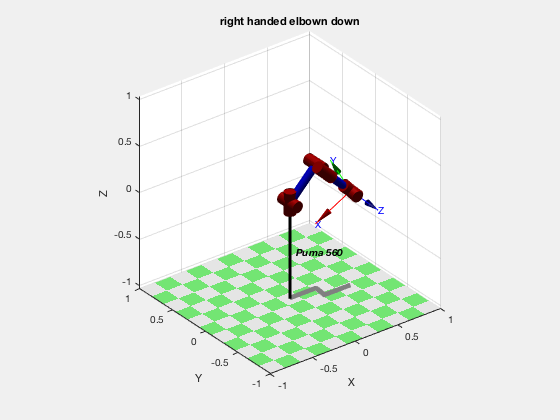

p560.plot(q1);

        q1(4)+q1(6)      

ans = -5.9832

## 7.3  Trajectories

## 7.3.1  Joint-space motion

mdl_puma560
qn

qn =          0    0.7854    3.1416         0    0.7854         0


T1 = SE3(0.4, 0.2, 0) * SE3.Rx(pi);
T2 = SE3(0.4, -0.2, 0) * SE3.Rx(pi/2);

q1 = p560.ikine6s(T1);
q2 = p560.ikine6s(T2);

t = [0:0.05:2]';

q = mtraj(@tpoly, q1, q2, t);

q = mtraj(@lspb, q1, q2, t);

q = jtraj(q1, q2, t);

[q,qd,qdd] = jtraj(q1, q2, t);

q = p560.jtraj(T1, T2, t)

q =     3.2631    2.0791    0.5992   -0.0000    0.4633    0.1215
    3.2629    2.0791    0.5992   -0.0003    0.4634    0.1217
    3.2620    2.0791    0.5992   -0.0027    0.4642    0.1228
    3.2596    2.0791    0.5992   -0.0087    0.4662    0.1257
    3.2551    2.0791    0.5992   -0.0199    0.4700    0.1310
    3.2482    2.0791    0.5992   -0.0373    0.4758    0.1394
    3.2384    2.0791    0.5992   -0.0618    0.4840    0.1512
    3.2255    2.0791    0.5992   -0.0940    0.4949    0.1667
    3.2094    2.0791    0.5992   -0.1344    0.5084    0.1861
    3.1899    2.0791    0.5992   -0.1832    0.5248    0.2096


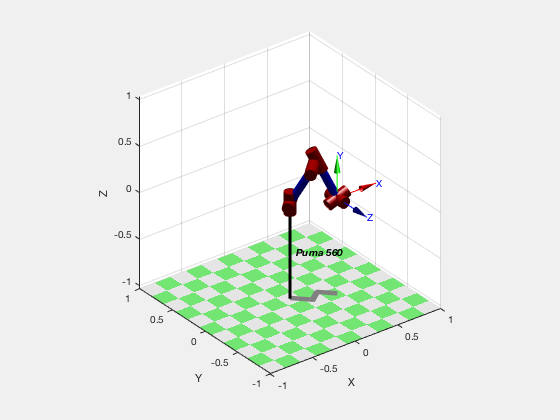

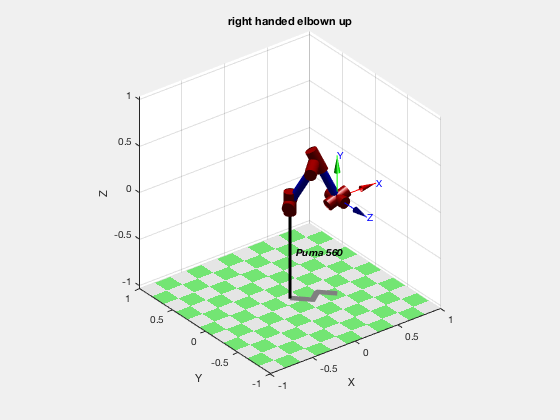


clf
p560.plot(q)

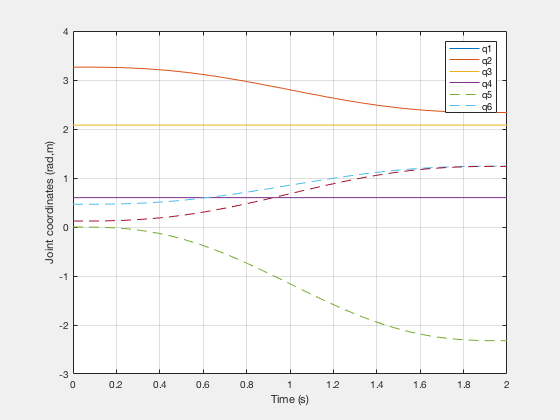


clf
plot(t, q(:,2))

qplot(t, q);

    
T = p560.fkine(q);

p = T.transl;
% 
about(p)

p [double] : 41x3 (984 bytes)


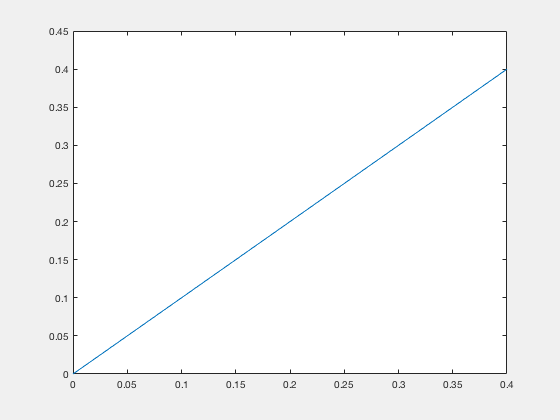


plot(p(:,1), p(:,2))

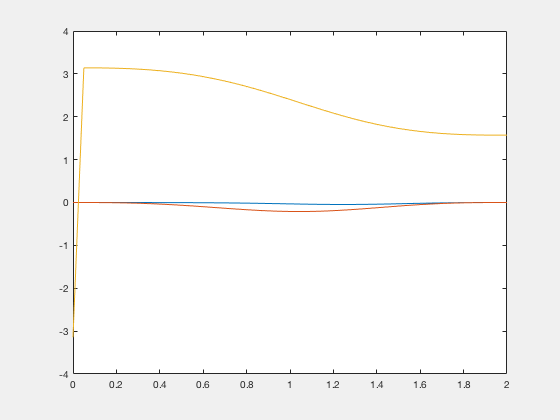


plot(t, T.torpy('xyz'))

## 7.3.2  Cartesian motion

Ts = ctraj(T1, T2, length(t));

plot(t, Ts.transl);

plot(t, Ts.torpy('xyz'));

qc = p560.ikine6s(Ts);

## 7.3.3  Kinematics in Simulink

sl_jspace

## 7.3.4  Motion through a singularity

T1 = SE3(0.5, 0.3, 0.44) * SE3.Ry(pi/2);
T2 = SE3(0.5, -0.3, 0.44) * SE3.Ry(pi/2);

Ts = ctraj(T1, T2, length(t));

qc = p560.ikine6s(Ts)
p560.plot(qc)
qplot(qc)

## 7.3.5  Configuration change

            T = SE3(0.4, 0.2, 0) * SE3.Rx(pi);
            
            qr = p560.ikine6s(T, 'ru');
            ql = p560.ikine6s(T, 'lu');
            
            q = jtraj(qr, ql, t);
            
            p560.plot(q)
            qplot(q)

 
L1 = 
Revolute(mod): theta=q, d=1, a=0, alpha=0, offset=0
